## Exercice 1



N=100;
h=1/(N+1);
a=[ones(N-1,1);0];
un1=a;
for i=1:N-2
    un1=[un1;a];
end
un1=[un1;ones(N-1,1)];
un2=ones(N^2-N,1);
A=1/h^2*(4*eye(N^2)-diag(un2,N)-diag(un2,-N)-diag(un1,1)-diag(un1,-1));
f=inline('2*pi^2*sin(pi*x)*sin(pi*y)');
fsolu=inline('sin(pi*x)*sin(pi*y)');

fsolu =

     Inline function:
     fsolu(x,y) = sin(pi*x)*sin(pi*y)



xi=linspace(0,1,N);
yi=linspace(0,1,N);

G=zeros(N);
Gex=zeros(N);
for i=1:N
    for j=1:N
        G(i,j)=f(xi(i),yi(j));
        Gex(i,j)=fsolu(xi(i),yi(j));
    end
end
F=[];
Uex=[];
for i=1:N
    F=[F;G(i,:)'];
    Uex=[Uex;Gex(i,:)'];
end
U=A\F;
V=[];
Vex=[];
for i=1:N
    V=[V;U((1+N*(i-1)):N*i)'];
    Vex=[Vex;Uex((1+N*(i-1)):N*i)'];
end
%Erreur
Erreur=norm(V-Vex ,"inf")/norm(V,"inf");
disp(["Erreur relative en norme infinie : ",num2str(Erreur)]);

    "Erreur relative en norme infinie : "    "0.030459"



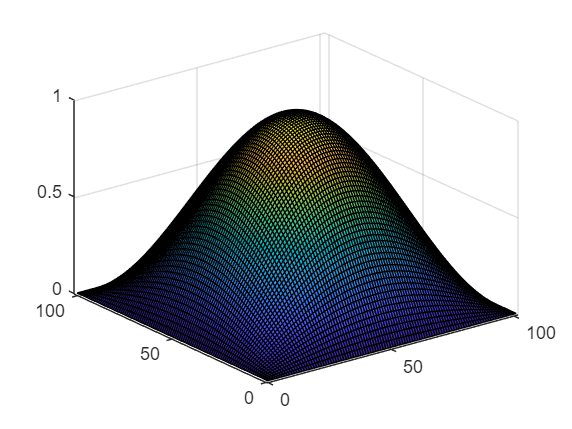

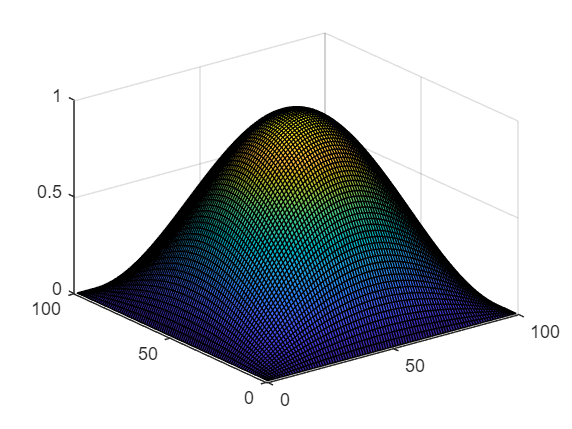


colzero=zeros(N,1);
ligzero=zeros(1,N+2);
Ucomplet=[ligzero;[colzero ,V ,colzero];ligzero];
surf(Ucomplet);

## Exercice 2

# Defi 1

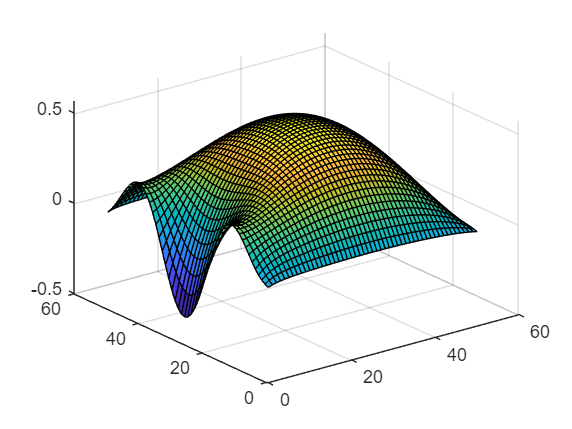


N=51;
h=1/(N+1);
a=[ones(N-1,1);0];
un1=a;
for i=1:N-2
    un1=[un1;a];
end
un1=[un1;ones(N-1,1)];
un2=ones(N^2-N,1);
A=1/h^2*(4*eye(N^2)-diag(un2,N)-diag(un2,-N)-diag(un1,1)-diag(un1,-1));
xi=linspace(0,1,N);
yi=linspace(0,1,N);



F=8*ones(N^2,1);
for j=1:N-1
    F(N*j+1,1)=F(N*j+1,1)+ 1/h^2*0.5*sin(pi*yi(j))*sin(3*yi(j)*pi);
end
U=A\F;
V=[];
for i=1:N
    V=[V;U((1+N*(i-1)):N*i)'];
end
surf(V)

V((N-1)/2,(N-1)/2)

ans = 0.5684

# Defi 2

sum(sum(V))*h^2

ans = 0.2726

## Exercice 3

# Defi 3


N=21;
k=2;
h=1/(N+1);
a=[ones(N-1,1);0];
un1=a;
for i=1:N-2
    un1=[un1;a];
end
un1=[un1;ones(N-1,1)];
un2=ones(N^2-N,1);
A=1/h^2*(4*eye(N^2)-diag(un2,N)-diag(un2,-N)-diag(un1,1)-diag(un1,-1));

xi=linspace(0,1,N);
yi=linspace(0,1,N);

F=(1+25*sin(k/4))*ones(N^2,1);
for j=1:N-1
    F(N*j+1,1)=F(N*j+1,1)+ 1/h^2*0.5*sin(pi*yi(j))*sin(k*yi(j)*pi);
end
U=A\F;

for l=1:10
    F=(1+25*sin(k/4))*ones(N^2,1);
    for j=1:N-1
        F(N*j+1,1)=F(N*j+1,1)+ 1/h^2*(0.5*sin(pi*yi(j))*sin(k*yi(j)*pi));
    end

    for i=1:N
        for j=1:N-1
            F(i+N*(j-1),1)=-1/h^2*8*U(i,j^3);
        end
    end
    U=A\F;
end

Index in position 2 exceeds array bounds. Index must not exceed 1.


V=[];
for i=1:N
    V=[V;U((1+N*(i-1)):N*i)'];
end
surf(V)